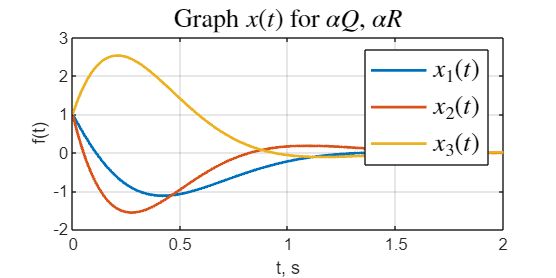

clear;
open_system('task_1_simm');
set_param('task_1_simm/x', 'VariableName', 'x')
set_param('task_1_simm/u', 'VariableName', 'u')

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
x0 = [1; 1; 1];

K1 = [-5.0390 -4.6284 -4.4944];
K2 = [-7.9405 -5.9449 -8.1697];
K3 = [-4.1539 -4.0983 -3.4959];
K4 = [-5.0390 -4.6284 -4.4944];

J1 = 21.7837;
J2 = 42.7327;
J3 = 174.5511;
J4 = 217.8366;
K = K4;


out = sim('task_1_simm');

figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
grid()
title('Graph $x(t)$ for $\alpha Q$, $\alpha R$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off